# Course 2. Example 2.1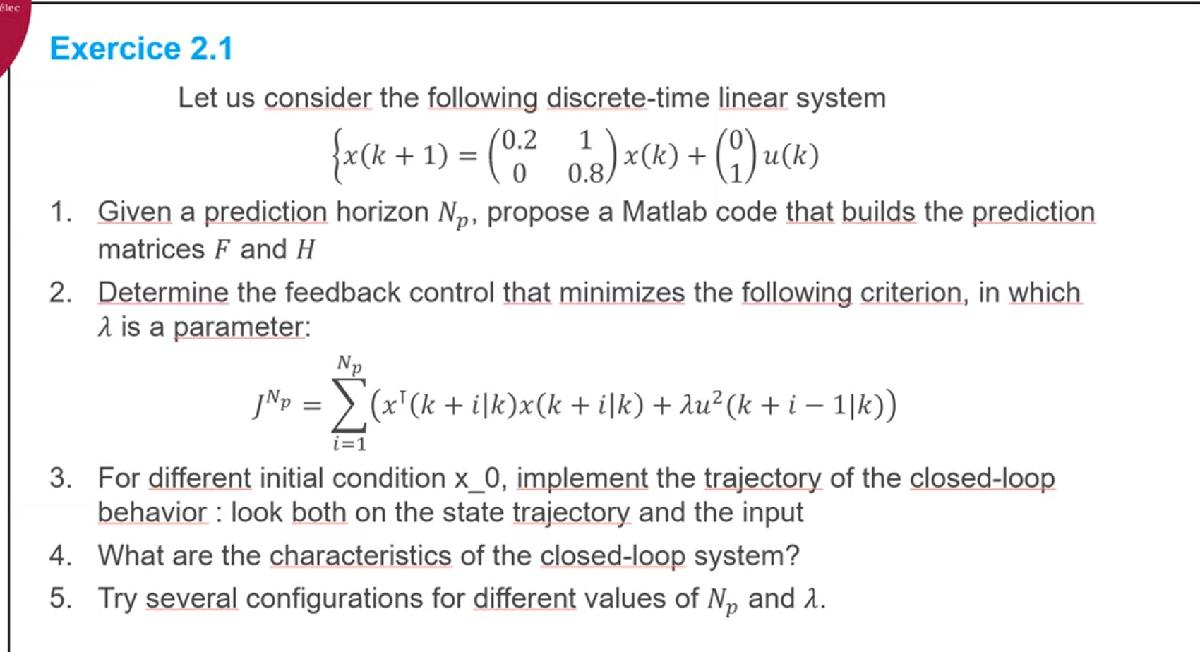

#### **Initialisation**

clear;
close all;
clc

% clear：清除工作空间的所有变量
% close all：关闭所有的Figure窗口
% clc：清除命令窗口的内容，对工作环境中的全部变量无任何影响

#### **Q1: Model prediction**

% System definition
A=[0.2 1; 0 0.8];
B=[0; 1];
nx=size(A,1);
nu=size(B,2);

% Model prediction
Np=4; % Receding Horizon
F=zeros(Np*nx,nx);
H=zeros(Np*nx,Np*nu);

for i=1:Np
    F(nx*(i-1)+1:nx*i,:)=A^i ; % F
    for j=1:i
        H(nx*(i-1)+1:nx*i,nu*(j-1)+1:nu*j)=A^(i-j)*B; % H
    end
end


#### Q2: Feedback Control

% Objective function
lambda=1;

Q=eye(nx); % Q is unitary matrix
R=lambda; % lambda  is a constant parameter

Qx=zeros(nx*Np);
Ru=zeros(nu*Np);

for i =1:Np
    Qx(nx*(i-1)+1:nx*i,nx*(i-1)+1:nx*i)=Q; %Qx
    Ru(nu*(i-1)+1:nu*i,nu*(i-1)+1:nu*i)=R; %Ru
end

#### Q3: Optimal feedback (off-line computation)

First=zeros(nu,nu*Np);
First(nu,nu)=eye(nu); 

K_Np=First*(H'*Qx*H+Ru)^(-1)*H'*Qx*F; % independent from k

#### Q3: Closed-loop implementation

Nsimu=50;
% initial x_0
xinit=[1;1];
xk=xinit;
X = [];
for i=1:Nsimu
    X = [X xk];
    uk=-K_Np*xk; %optimal control
    xkp1=A*xk+B*uk;
    xk=xkp1;
end

% plot
X

X =     1.0000    1.2000    0.3911    0.0884    0.0147    0.0014   -0.0002   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    1.0000    0.1511    0.0102   -0.0030   -0.0016   -0.0004   -0.0001   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0

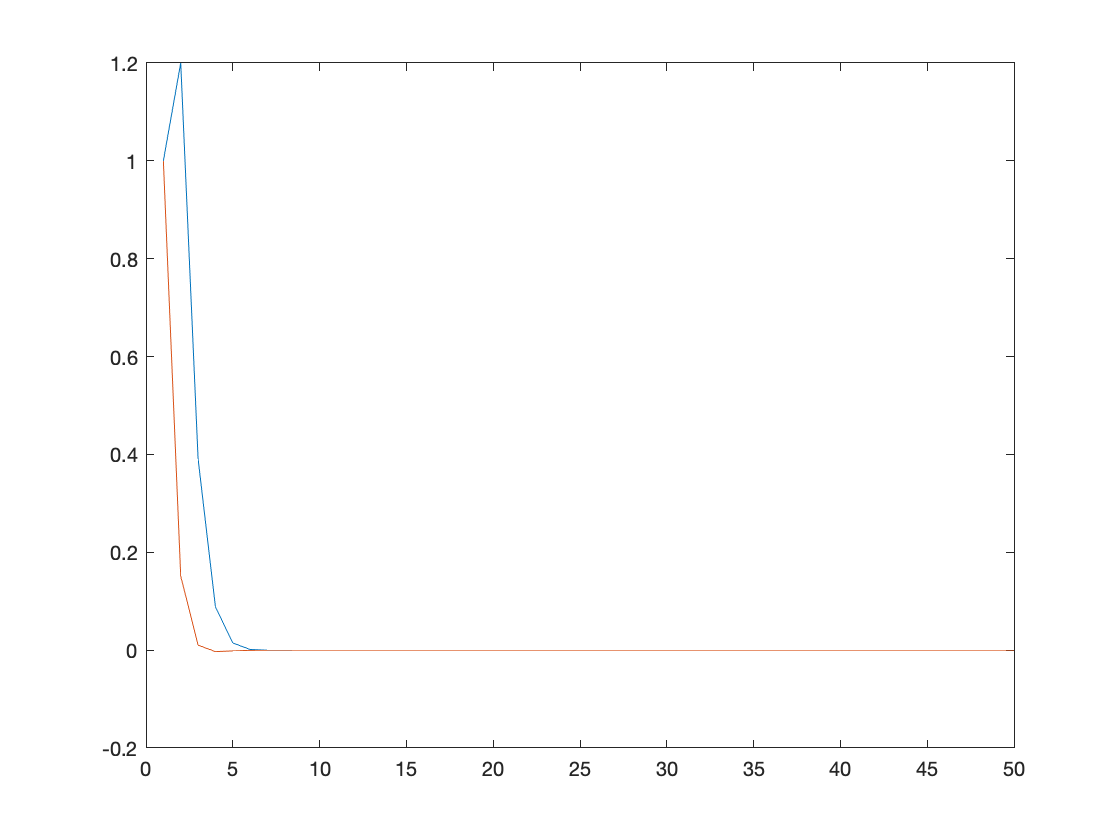

plot(1:Nsimu,X);

#### Q4: Analysis of the closed-loop system

eigenvalues=eig(A-B*K_Np)

eigenvalues =    0.1815 + 0.1080i
   0.1815 - 0.1080i


modeul = norm(eigenvalues(1),1)

modeul = 0.2112

x is convergent to zero;

stable;

#### Q5: several configurations